# 숙제#12: 자세결정 및 제어부 실습 

**[2026-봄] 인공위성 시스템(ASE4080), 인하대학교 항공우주공학과**

**김창오 박사과정(cokim@inha.edu)**

#### 1. 자세제어 Part1: 자기토커 기반 제어

시뮬레이션 조건은 다음과 같다.

위성체

- 초기 궤도 $r^{\textrm{ECI}} \left(t_0 \right)={\left\lbrack \begin{array}{ccc}
0 & -6878\ldotp 137 & 0
\end{array}\right\rbrack }^T \;\left\lbrack \textrm{km}\right\rbrack$     $v^{\textrm{ECI}} \left(t_0 \right)={\left\lbrack \begin{array}{ccc}
0 & 0 & 7\ldotp 612608
\end{array}\right\rbrack }^T \;\left\lbrack \textrm{km}/s\right\rbrack$

- 초기 자세 $C_{\textrm{ORF}}^{\textrm{BRF}} =I_3$ (즉 BRF = ORF , Roll=Pitch=Yaw=0 deg)

- 초기 각속도 $\omega_{b/i}^b =\left\lbrack \begin{array}{ccc}
3 & 3 & 3
\end{array}\right\rbrack \;\deg /s$

- 관성 모멘트 $J=\textrm{diag}\left(\left\lbrack \begin{array}{ccc}
0\ldotp 032 & 0\ldotp 007 & 0\ldotp 032
\end{array}\right\rbrack \right)\;\;\left\lbrack \textrm{kg}\;\;m^2 \right\rbrack$

센서 및 구동기

- 자기 센서, 자이로 탑재. 측정 오차 없음  (지자기 벡터와 위성의 각속도 측정 가능)

- 자기토커는 총 3개가 탑재되었으며, 동체 좌표계(BRF)의 x,y,z 축과 정렬되어 있다고 가정한다.

시뮬레이션

- 종료 시간: 3 궤도

우주 환경 및 시간

- 궤도 외란: 없음 (이체모델 적용. 원하면 블록에서 드롭다운으로 추가 가능)

- 자세 외란: 없음 (원하면 중력 구배 토크 추가 가능)

- 시간: (UTC) 2026년 5월 19일 12시 0분 0초 

지자기장 모델은 다음과 같이 단순한 다이폴 모델이 적용되어 있다. NED 좌표계에서 표현하면 다음과 같다. 다음을 참고한다.

[https://en.wikipedia.org/wiki/Dipole_model_of_Earth%27s_magnetic_field](https://en.wikipedia.org/wiki/Dipole_model_of_Earth%27s_magnetic_field) 

$b^{\textrm{NED}} =\left\lbrack \begin{array}{c}
b_N \\
b_E \\
b_D 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
B_0 {\left(R_E /r\right)}^3 \cos \delta \\
0\\
{2B}_0 {\left(R_E /r\right)}^3 \sin \delta 
\end{array}\right\rbrack$,  $\left\|\mathit{\mathbf{b}}\right\|=B_0 {\left(\frac{R_E }{r}\right)}^3 \sqrt{1+3\cos^2 \delta }$

참고로 $B_0 =3\ldotp 12\times {10}^{-5} \left\lbrack T\right\rbrack ,R_E =6378\ldotp 137\;\left\lbrack \textrm{km}\right\rbrack$이다. $r,\delta ,\alpha$는 각각 거리, 적위(declination), 적경(right ascension)으로 ECI 좌표 성분 ${\mathit{\mathbf{r}}}^{\textrm{ECI}} ={\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack }^I$로부터 아래와 같이 구할 수 있다. 


$$r=\sqrt{x^2 +y^2 +z^2 },\delta =\sin^{-1} \left(z/r\right)\;\;,\alpha =\textrm{atan2}\left(y,x\right)\;,C_{\textrm{ECI}}^{\textrm{NED}} =\left\lbrack \begin{array}{ccc}
\sin \delta  & 0 & -\cos \delta \\
0 & 1 & 0\\
\cos \delta  & 0 & \sin \delta 
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
-1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
\cos \alpha  & \sin \alpha  & 0\\
-\sin \alpha  & \cos \alpha  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


### vv 아래는 수정하지 않도록 한다 vv

clc; clear; close all
% vvvvvvvvvvvvvvvvvvv  Parameter (Do not Modify)  vvvvvvvvvvvvvvvvvvvv
R_E             =   6378.137;              % [km]
mu_E            =   398600.4418;           % [km^3/s^2]
R2D             =   180/pi;
D2R             =   pi/180;
W_E             =   7292115.0 * 10^-11;    % [rad/s] 
m2km            =   1e-3;
km2m            =   1e3;

addpath(fullfile(pwd, 'library'));

% ============= Satellite =============
r0_eci          = [0 -6878.137 0]';  % position of satellite [km]
v0_eci          = [0 0 7.612608]';   % velocity of satellite [km/s]

% OE
a               = vis_viva(r0_eci,v0_eci,[],1); % Semi-major axis of orbit [km]
[e,ee]          = eccentricity(r0_eci,v0_eci);  % Eccentricity vector of orbit []

% Attitude : Find q0 (initial attitude quaternion)
z_orf           = -r0_eci/norm(r0_eci);
y_orf           = -cross(r0_eci,v0_eci)/norm(cross(r0_eci,v0_eci));
x_orf           = cross(y_orf,z_orf);
DCM0_eci2orf    = [x_orf' ; y_orf' ; z_orf'];
DCM0_orf2brf    = eye(3);

DCM0_eci2brf    = DCM0_orf2brf * DCM0_eci2orf;
q0_eci2brf      = DCM2Quaternion(DCM0_eci2brf);

% Rotation velocity
w_b_i2b         = [3 3 3];  % rotation velocity of the satellite [deg/s]

% MOI
J               = diag([0.032 0.007 0.032]);     % [kg m^2]

% ============= Simulation time =============
period          = 2*pi*sqrt(a^3/mu_E);
sim_time        = 3*round(period);
SIM_dt          = 1;

startdate       = juliandate(2026, 5, 19, 12, 0, 0);

% ^^^^^^^^^^^^^^^^^^^^^^^^  Parameter (Do not modify)  ^^^^^^^^^^^^^^^^^^^^^^^^

**1.1**) 'B-dot control' 기법은 자기토커를 이용하여 위성의 각속도를 감쇠하거나, 리액션휠의 누적된 모멘텀을 감소시키는 기법이다. 자세하게는 자기토커의 다이폴 모멘트와 지구 자기장이 상호작용하면서 토크가 생성되는 방식인데, 다이폴 모멘트의 크기에 따라 제어 토크가 결정된다. 따라서 회전하고 있는 위성을 목표 각속도까지 감쇠시키기 위해서는 적절한 다이폴 모멘트 크기를 갖는 자기토커 선정이 필요하다.

[https://satsearch.co/products/categories/satellite/attitude/actuators/magnetorquer](https://satsearch.co/products/categories/satellite/attitude/actuators/magnetorquer) 

**Q) **위와 같은 위성 제품 판매 사이트에서 3U 규격에 장착할 수 있는 자기토커를 선정하고** (1) 선택한 이유를 설명하시오. **그리고 데이터시트에 제공된 다이폴 모멘트 크기를 아래 셀의 파라미터로 입력하시오. 이후 시뮬링크 모델을 실행하고 PLOT 버튼을 눌러** (2) 3궤도 이내에 위성이 몇 deg/s까지 감쇠했는지, (3) 그때 다이폴 모멘트 명령은 어떻게 나왔는지 결과 그래프와 함께 설명하시오.**

% Margnetorquer dipole moment
% 변수명은 수정하지마시오.
Max_dipole = 0.3;               % [Am^2] 

#### **1.1 답변**

- **선정 자기 토커 : **Kongsberg NanoAvionics Magnetorquers MTQ M6P(https://satsearch.co/products/kongsberg-nanoavionics-cubesat-magnetorquer)

- **선정 이유 :  **PC/104 폼팩터(90×96 mm)는 3U CubeSat의 표준 내부 스택 규격과 일치하여 별도 브래킷이나 개조 없이 위성 구조체에 바로 장착 가능하므로, 한정된 3U 부피 예산에서 유리하고, X, Y축 자기토커 로드 2개와 Z축 에어코어 코일 1개가 단일 PCB에 통합되어 있어 시스템 복잡도와 조립 오류 가능성을 줄일 수 있다는 장점이 있어 선정하였습니다.

- 선정된 자기 토커의 Max_dipole 값은 X, Y가 0.3, Z가 0.34이다. 그러나 현재 코드 구조상 각 축의 Max 값을 선언할 수 없기 때문에 보수적으로 X, Y, Z 모두 0.3을 넘지 않도록 설정하기 위해서 Max_dipole을 0.3Am^2으로 선정하였다.

- **그래프 설명**

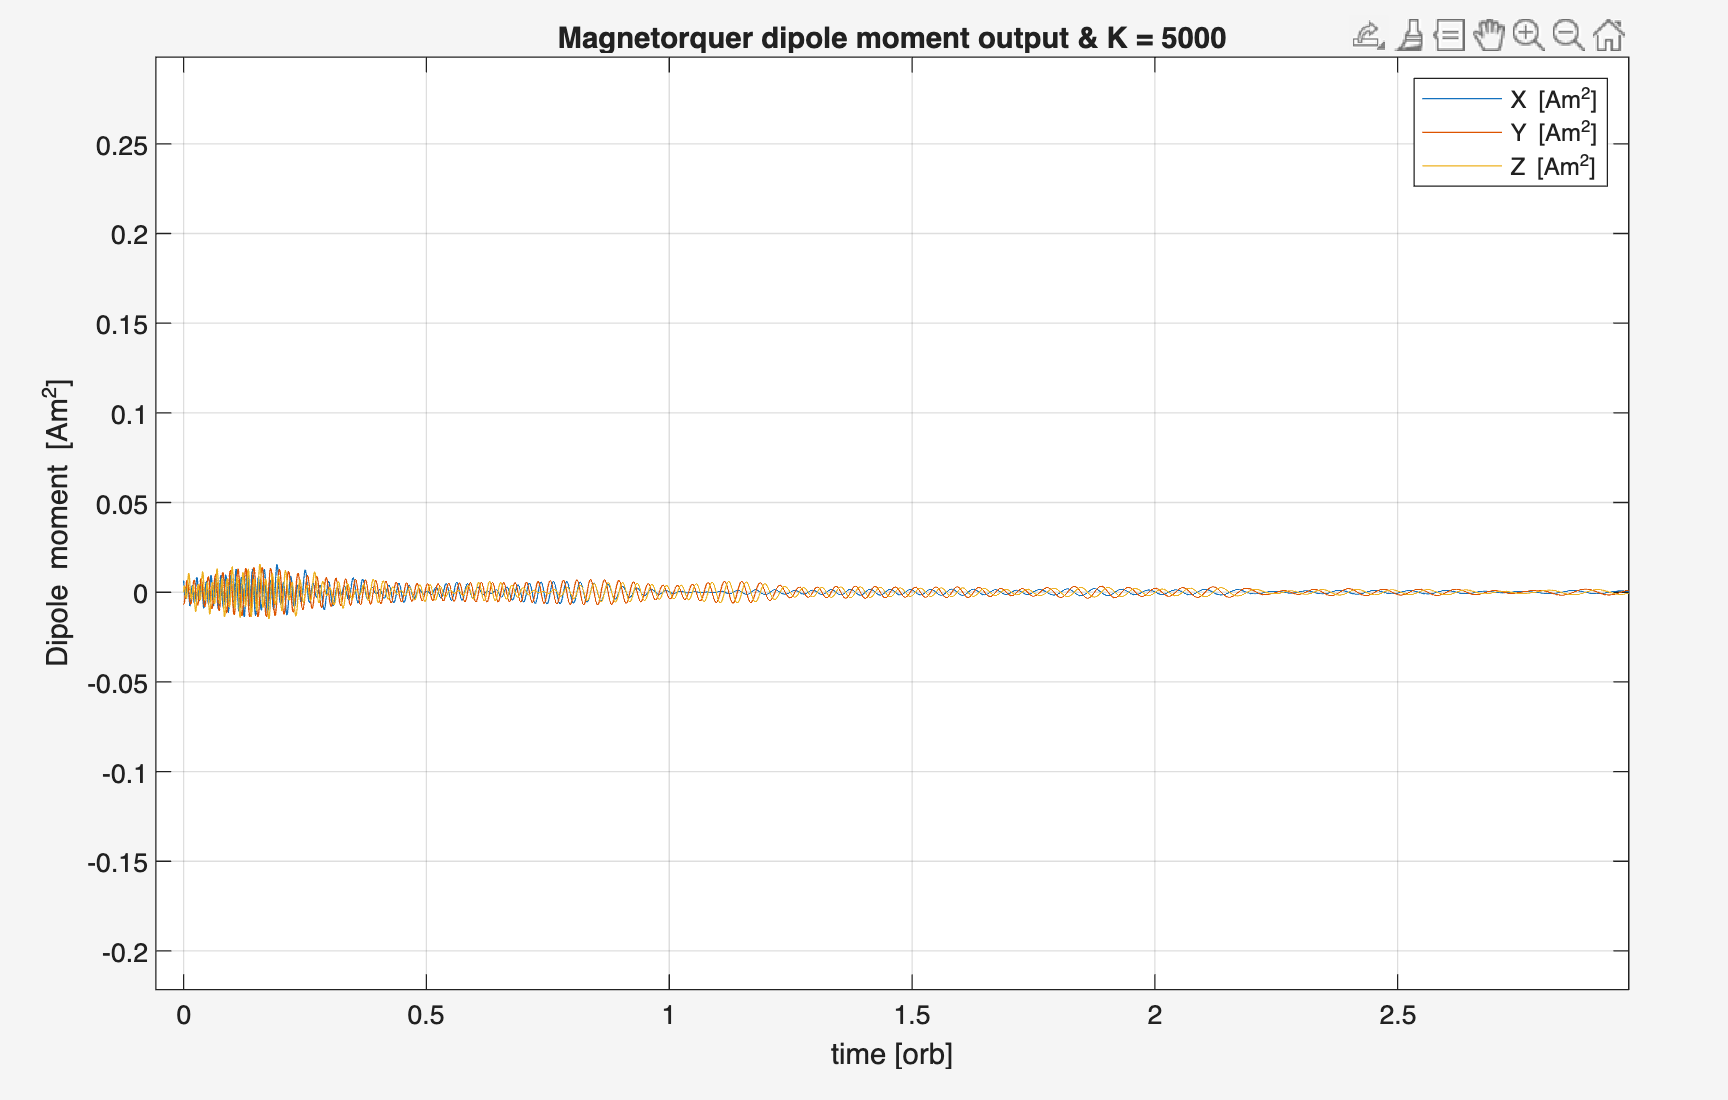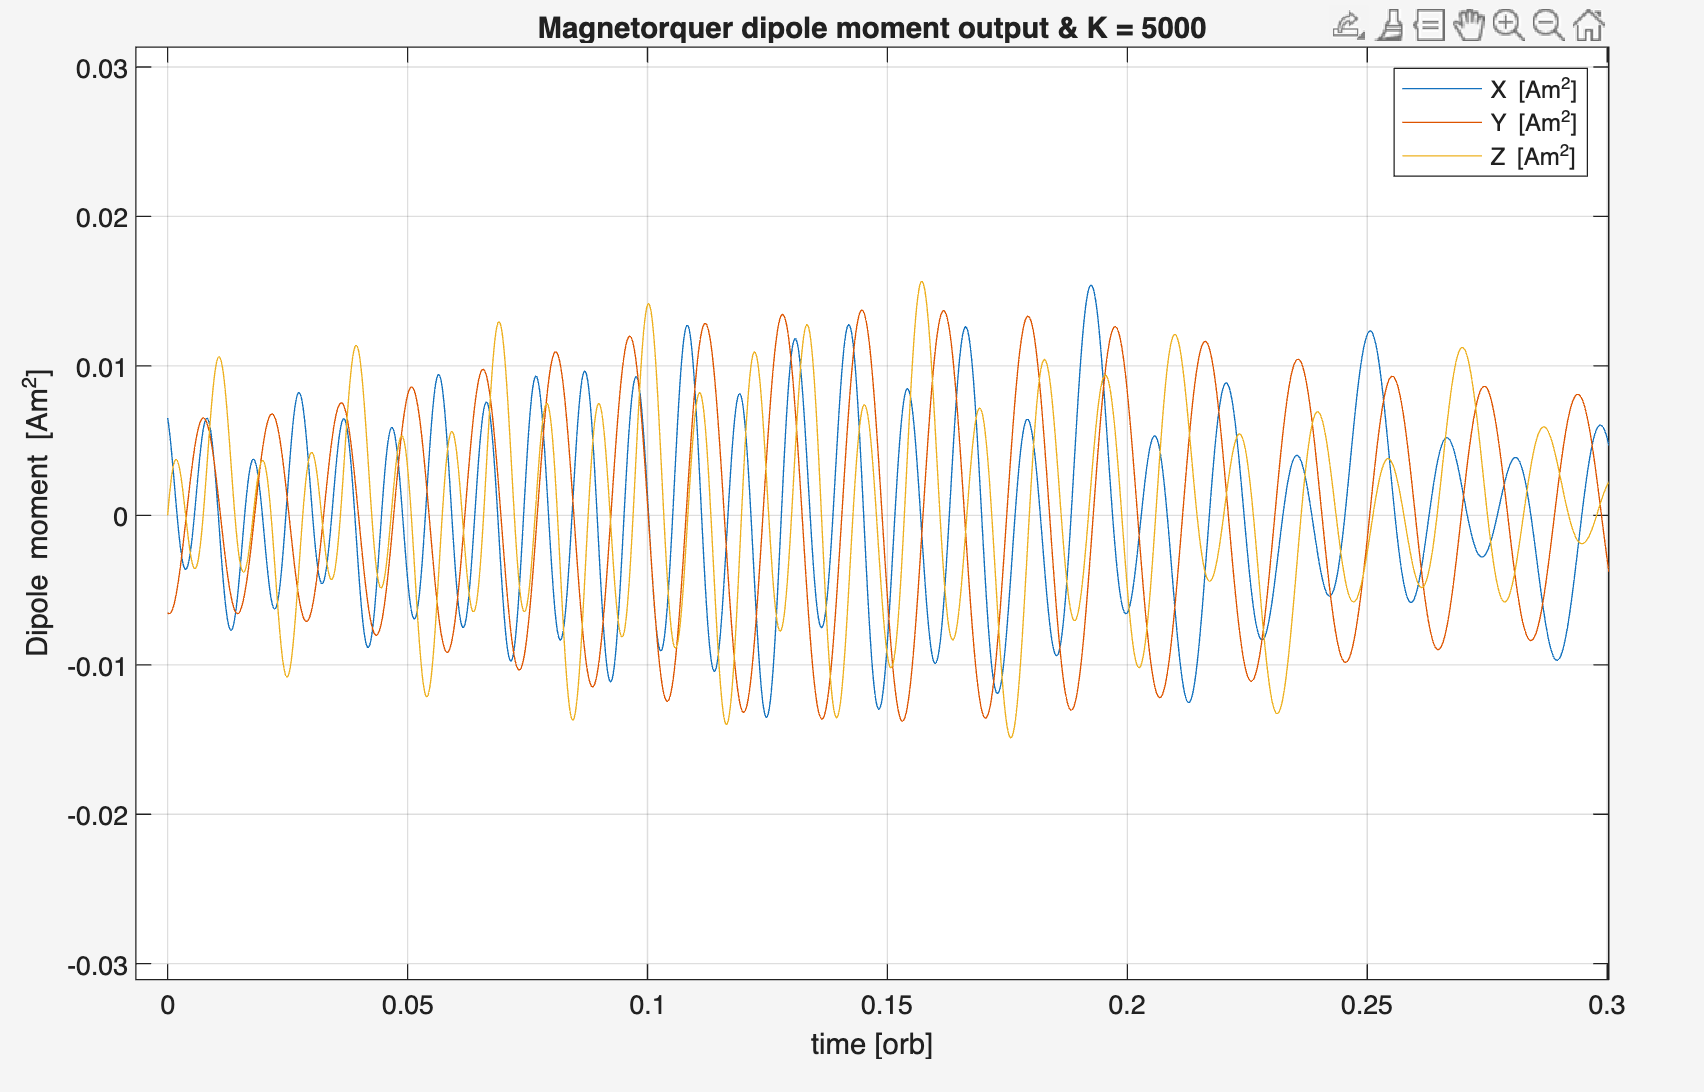

- 먼저 Dipole moment 명령인 Dipole moment output 그래프를 보면, 초기 위성의 디텀블링을 제어하기 위해서 구동명령이 초반부에 밀집되어있다가, 의도한 대로 나중에는 각속도가 감쇠가 발생하여, 서서히 명령크기가 줄어드는 것을 확인할 수 있다. 위 우측 그래프에서 볼 수 있듯이 디텀블링을 잡기위한 초반부 0~0.3orbit 동안 X, Y, Z 축 모두 모두 ± 0.02 이하로 명령이 나왔다. 이는 선정한 자기토커의 MAX 값이 0.3 Am^2을 넘지는 않는 것으로 판단되며 이후 감속도 감쇠로 초반값보다 모멘트 명령이 감소하므로 이를 통해 3orbit 동안 포화가 한 번도 발생하지 않음을 의미한다. 

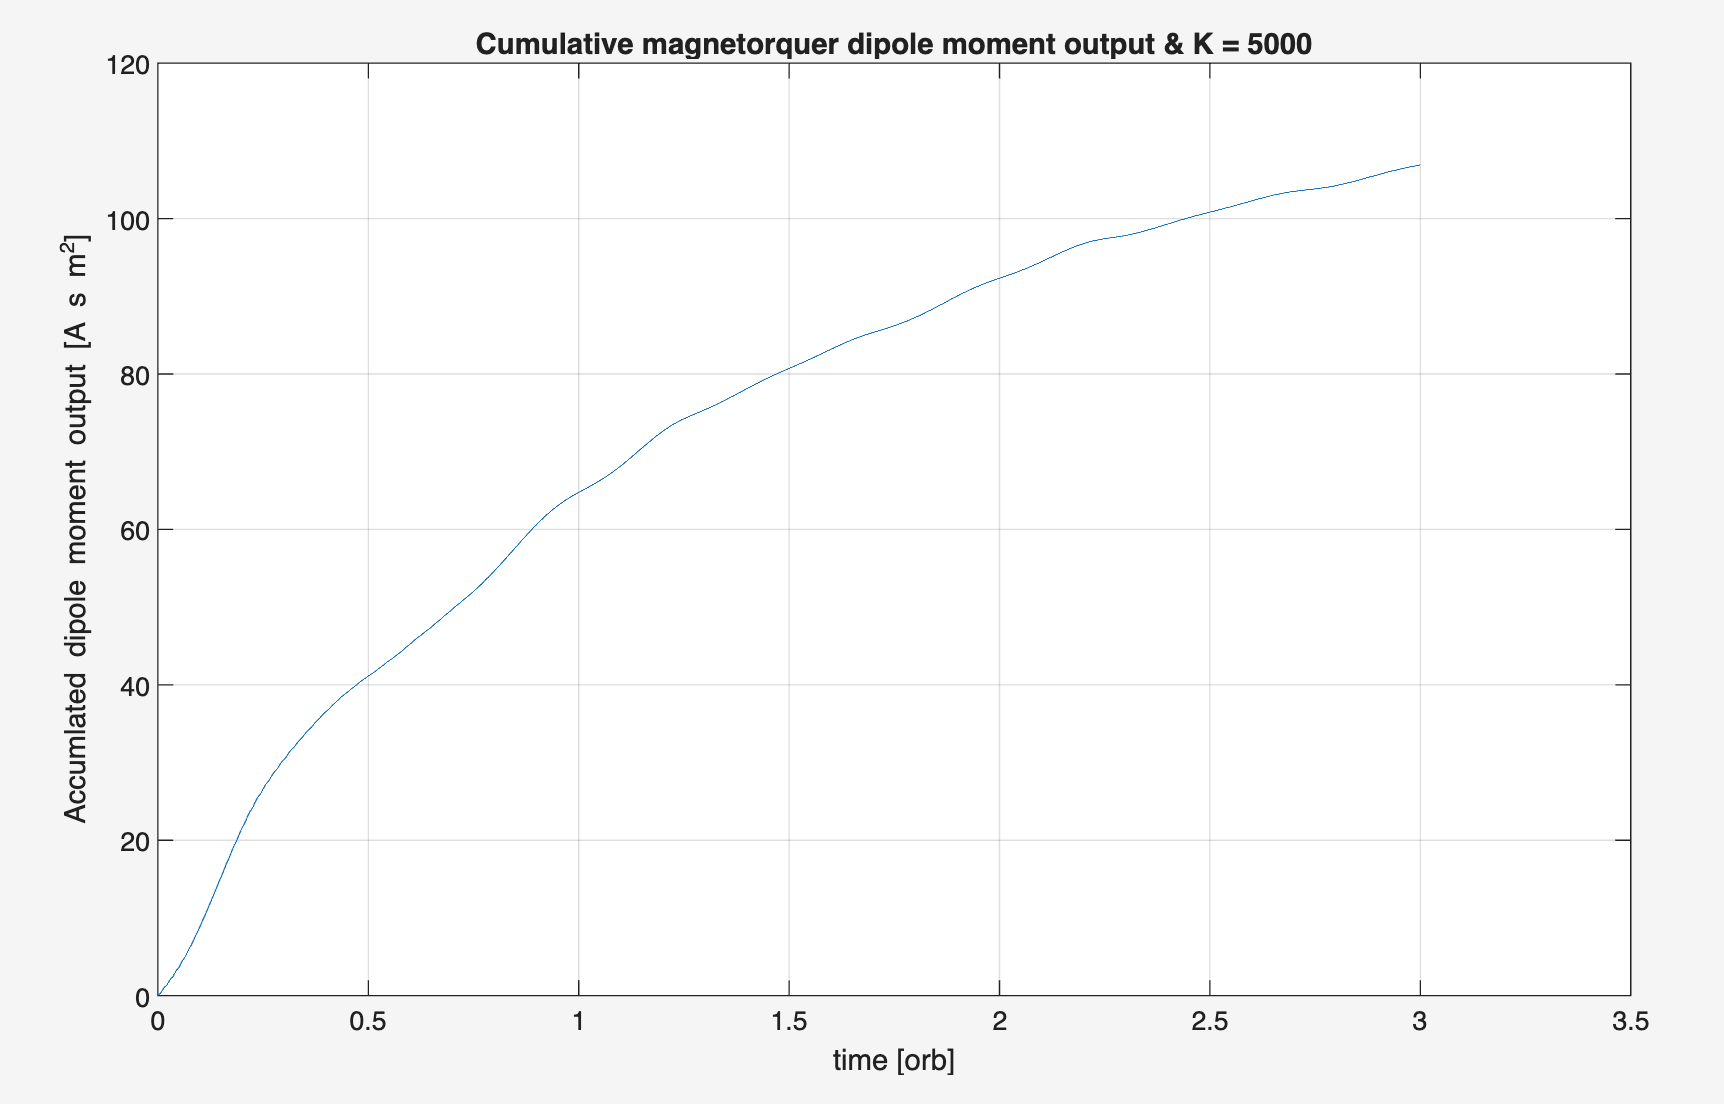

- 누적 다이폴 모멘트는 3궤도 동안 단조 증가하여 최종적으로 약 107 A·s·m² 에 도달했고, 초기(0 ~ 0.5 orb)에는 기울기가 가팔라 자기토커가 활발히 동작했고, 이후 각속도가 줄면서 기울기가 완만해짐을 관찰할 수 있다.. 이는 에너지 소모 관점에서 정상적인 B-dot 제어의 거동임을 의미한다. 

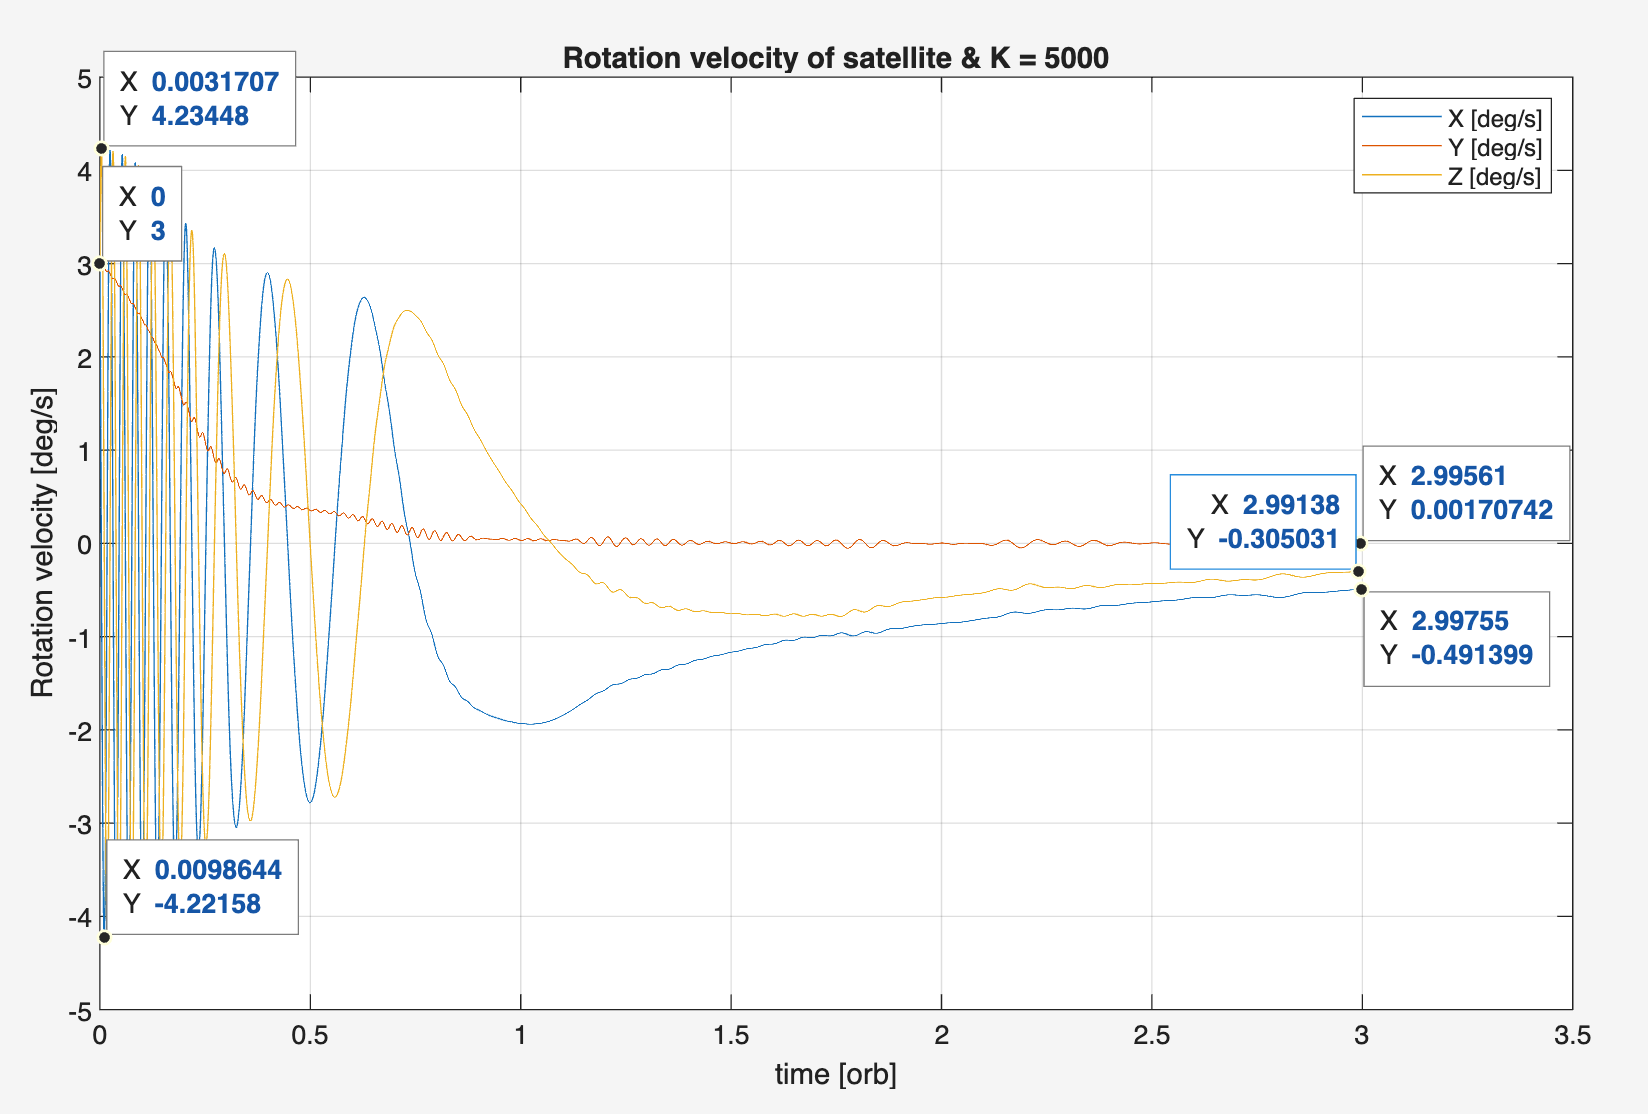

- 각속도 감쇠의 경우 X축의 경우 초반 ± 4.22158 deg/s에서 -0.491399deg/s로 감소함을 확인하였고, Y축의 경우 +3deg/s에서 0.0017deg/s까지 감소하였으며, Z축의 경우 ± 4.23448deg/s에서 -0.305031deg/s까지 감소하였다.  감쇠 양상을 축별로 정리하면 Y축은 약 1.0 orb 이내에 거의 완전히 수렴하여 3궤도 시점에서 0.0017 deg/s로 사실상 0에 도달하였다. X·Z축은 초기에 큰 진동을 보이며 느리게 감쇠하여, 3궤도 시점에서 각각 −0.491 deg/s, −0.305 deg/s의 잔류 각속도가 남아 있다. 세 축 전체를 종합하면, 초기 약 ±4 deg/s의 텀블링이 3궤도 이내에 0.5 deg/s 이하로 감쇠하였다.

**1.2 **B-dot 제어기의 제어 이득 K를 설계하시오. 

B-dot 제어의 성능은 자기토커 뿐만 아니라 제어 이득 (K)의 영향을 크게 받는다. 합리적인 제어 이득을 설계하기 위해 다양한 방법들이 연구되어 왔는데, 그 중 하나는 다음과 같다.

@ Avanzini, G., & Giulietti, F. (2012). Magnetic detumbling of a rigid spacecraft. *Journal of guidance, control, and dynamics*, *35*(4), 1326-1334.

============= 본 논문의 핵심 아이디어는 다음과 같다. 이 부분은 참고만 하도록 한다. ================== 

1) 자기토커는 지구 자기장에 수직한 방향의 제어토크만 만들 수 있다.

- 자기토커에 의한 토크는 $\tau =m\times b$ 이므로 항상 지구 자기장 $b$에 수직이다.

- 따라서 위성 각속도($\omega$)가 지구 자기장 벡터($b$)와 거의 평행해지면($\omega \;//\;b$), 자기토커로 유도되는 토크로는 위성 각속도를 줄이기 힘들어진다.

- 논문은 이러한 상황, 즉 $\omega \;//\;b$인 상황을 피하기 위해, 자기장에 수직한 동체 각속도 성분 $\omega_{\bot }$의 동역학을 분석하고, 적절한 제어 이득 $k_w$ 설계 방법을 제시한다.

2) 지구 자기장에 수직한 각속도 성분은 다음과 같다. $\omega_{\bot } =\left(I_3 -\hat{\mathit{\mathbf{b}}} {\hat{\mathit{\mathbf{b}}} }^T \right)\omega$.

3) 논문에서는 $\omega_{\bot }$의 시간에 따른 변화량을 -(자기토커 제어에 의한 Term)+(궤도 변화에 의해 생성되는 Term)으로 근사할 수 있음을 제시하고, 이 두 Term의 크기가 비슷해지도록 유도하는 제어 이득 $k_w$ 설계 방식을 제시한다. 더 자세한 수식은 논문을 참고하며, 결론적으로 논문에서 유도된 제어 이득은 아래와 같다.

=================================================================================


$$k_w =2n\left(1+\sin \xi_m \right)J_{\min }$$



$$K_{\textrm{bdot}} =\frac{k_w }{{\left\|\mathit{\mathbf{b}}\right\|}^2 }$$


where, $n:$ 궤도의 평균 운동 (mean motion, [rad/s]) , $J_{\min }$: 관성 모멘트 성분 중 가장 작은 값 $\left\lbrack \textrm{kg}\;m^2 \right\rbrack$ , $\xi_m$: 궤도 경사각과 지구 자기장 적도면이 이루는 각 = 궤도 각운동량 벡터와 지구 자기쌍극자 벡터가 이루는 각, $\left\|\mathit{\mathbf{b}}\right\|$: 지구 자기장 벡터의 크기

여기서 $\xi_m$은 시간에 따라 변하는 값이므로 B-dot 알고리즘의 게인 또한 시간에 따라 변해야 하는데, 실제 ADCS 소프트웨어에서 매 순간마다 이를 계산할 경우 구현 복잡도가 증가한다. 따라서 sine 함수의 성질을 이용하여 보수적으로 다음과 같이 Gain을 설계할 수 있다.

$k_w =2n\left(1+\sin \xi_m \right)J_{\min } \le 4{\textrm{nJ}}_{\min }$  ,   $K_{\textrm{bdot}} =\frac{k_w }{{\left\|\mathit{\mathbf{b}}\right\|}^2 }$

**Q)** 1.1에서는 아래 임의의 값을 제어 이득으로 사용하였다. 이제 바로 위에 있는 보수적인 $k_w$ 유도 식을 문제 1의 파라미터들을 활용하여 아래 코드에서 구현하고 **1.1**의 결과와 비교하시오. "K_bdot" 변수명은 그대로 사용하고, 자기장 벡터 크기는 문제 설명에 주어진 값을 활용하시오. **위성 각속도 변화, 다이폴 모멘트 누적 출력**을 비교하고, 본인이라면 게인 값을 어떻게 설정할지 간단하게 의견을 제시하시오.

K_bdot  = 5000;

% ==================== DIY ====================
J_min = min(diag(J));
n = sqrt(mu_E/a^3);
kw = 4*n*J_min; 
r_norm = norm(r0_eci); % orbit is circle orbit so r_norm constant
B0 = 3.12 * 10^-5;
delta = asin(r0_eci(3)/r_norm);
b_mag = B0*(R_E/r_norm)^3*sqrt(1+3*cos(delta)^2);

K_bdot = kw/b_mag^2;
% ==================== DIY ====================

- delta는 위에서 제공된 초기위치를 통하여 산출하였고, kw는 최대값인 sin이 1일때로 계산하여 K_bdot을 산출하였다. 그 결과 gain이 12517로 산출되었다.

- 위성 각속도 변화, 다이폴 모멘트 누적 출력은 다음과 같다.

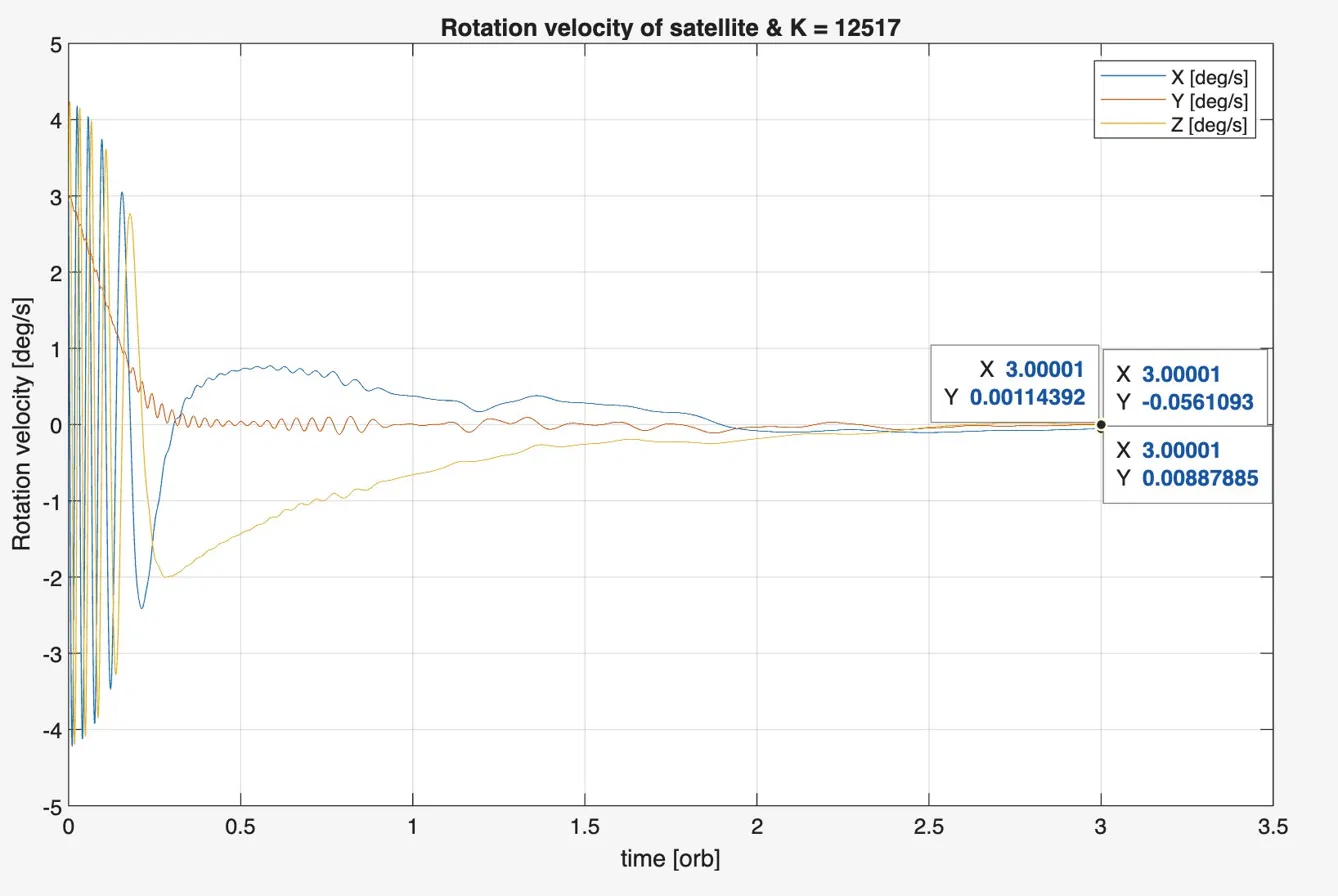

- K=12517에서는 3궤도 시점 잔류 각속도가 X축 −0.056, Y축 0.0011, Z축 0.0089 deg/s로, K=5000의 X축 −0.491, Z축 −0.305 deg/s에 비해 **약 10배 이상 감쇠 성능이 향상**되었다. 특히 K=5000에서 잔류가 컸던 X·Z축이 K=12517에서는 거의 0에 수렴하였다. 다만 초반 과도 응답을 보면, K=12517에서 X축이 약 −2.5 deg/s까지 언더슈트가 발생하고 1.5 orb까지 진동이 지속되는 반면, K=5000은 상대적으로 부드럽게 감쇠하였다. 이는 게인이 클수록 초기 제어 명령이 강해져 과도 응답이 커지는 트레이드오프 관계를 보여준다.

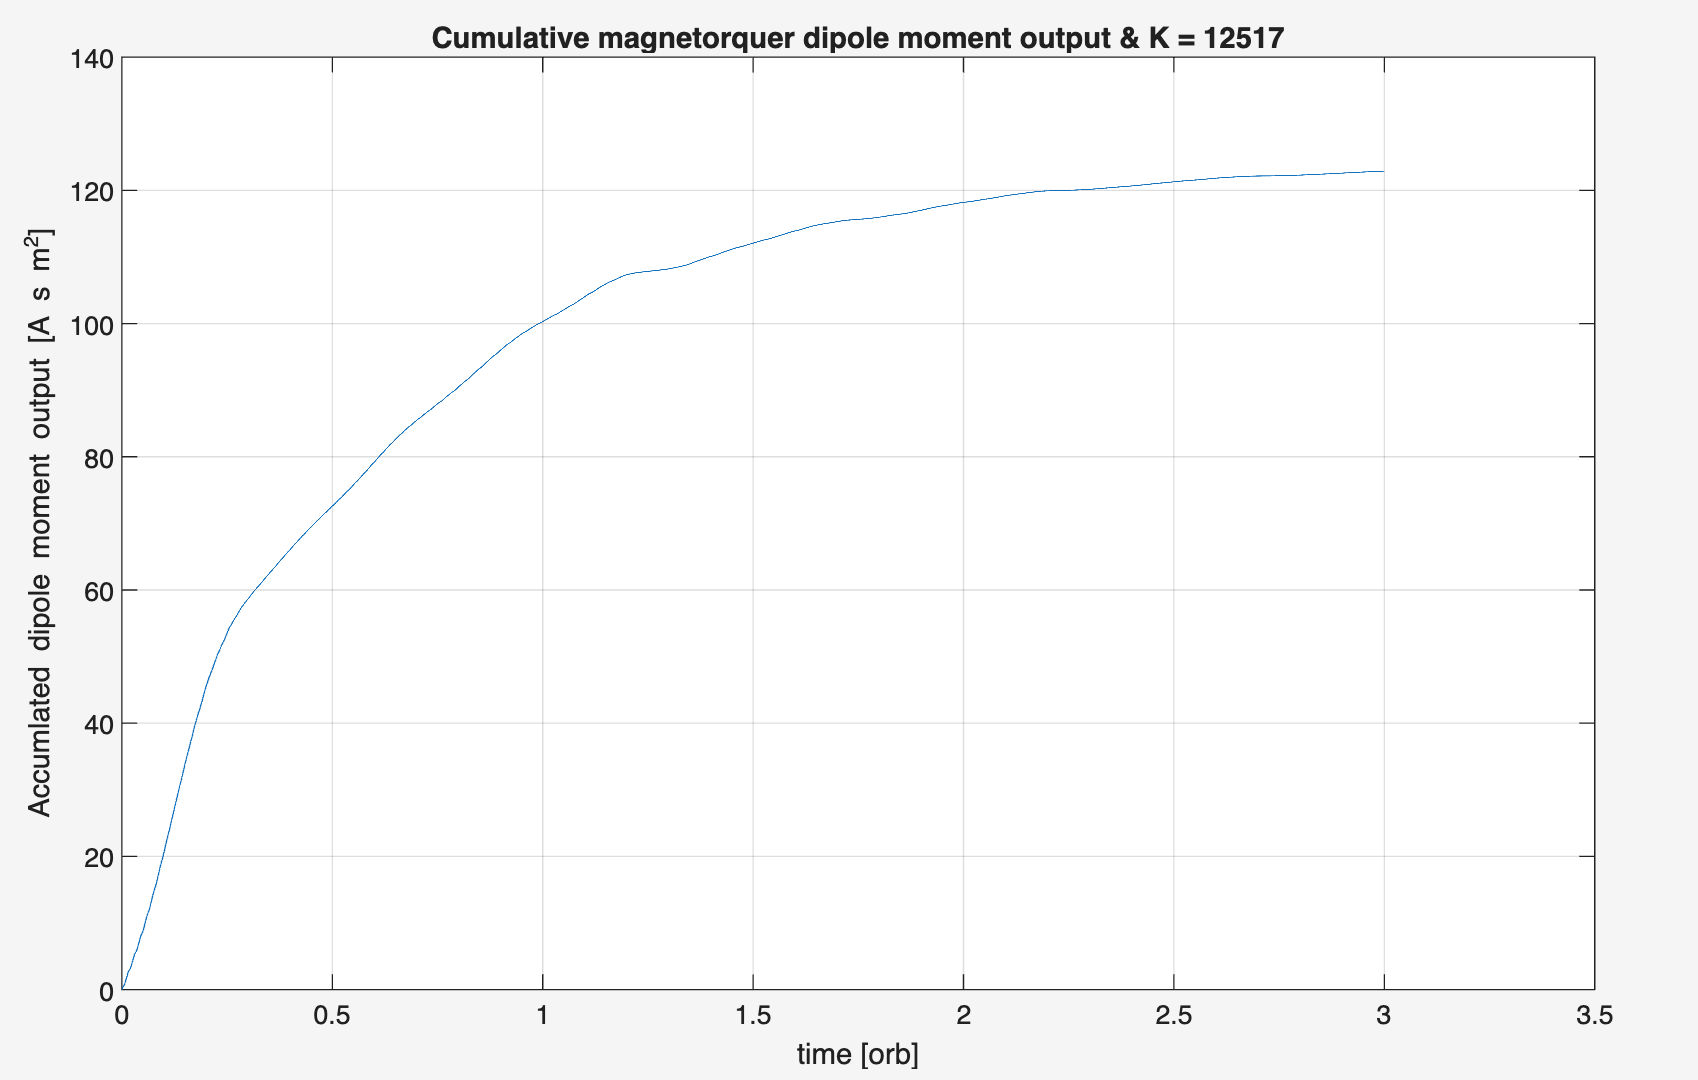

- 누적 다이폴 모멘트의 경우, K=12517은 K=5000의 107 A·s·m²보다 큰 약 125 A·s·m²에 도달하였다. 초반 기울기는 K=12517이 더 가팔라 초기 디텀블링을 위해 더 많은 모멘트 명령이 집중되었음을 알 수 있다. 이후 각속도가 수렴함에 따라 두 경우 모두 기울기가 완만해지는 동일한 경향을 보이나, K=12517은 더 빠른 시점에 기울기가 감소하기 시작하였다. 이는 게인이 클수록 초기에 더 많은 에너지를 소모하지만 더 빠르게 안정화됨을 의미한다.

- 위 K=12517은 sin ξm=1로 가정한 보수적 상한값이다. 게인이 클수록 초기 디텀블링을 빠르게 제거할 수 있지만, 그만큼 자기토커에 더 큰 전류가 흘러 전력 소모가 증가한다. 전력 예산이 제한적인 3U CubeSat에서는 과도하게 큰 게인이 오히려 불리할 수 있다. 따라서 본인이라면 sin ξm=0.5\sin\xi_m = 0.5 sinξm�=0.5를 적용하여 kw=2n(1+0.5)Jmin =3nJmin � 으로 게인을 산정할 것이다. 이 경우 K는 임의로 설정한 5000보다는 크고 12517보다는 작은 값으로, 감쇠 반응성과 전력 효율 사이의 균형을 취한 선택이다.

#### 2. 자세제어 Part 2: 리액션 휠 성능 결정 

1축 제어 문제를 가정한다. 다음 두 가지 제약 조건을 각각 만족하기 위한 리액션 휠의 성능(각운동량 $h_{\textrm{RW},\max }$ 과 토크 $\tau_{\textrm{RW},\max }$)을 결정하시오.

자세 파라미터는 다음과 같다.

$\theta$: 위성 자세 [deg], $\omega$: 위성 각속도  [deg/s], $a$: 위성 각가속도  [deg/s^2], $I_s =0\ldotp 10\;\;\left\lbrack {\textrm{kgm}}^2 \right\rbrack$: 위성 관성 모멘트(1축 기동 가정)

제약 조건은 다음과 같다.

- 위성은 15초만에 10도에 도달할 수 있어야 한다. $\theta \left(t=15\right)={10}^{\circ } \;\;\&\;T=15$

- 위성은 25초만에 20도에 도달할 수 있어야 한다. $\theta \left(t=25\right)={20}^{\circ } \;\;\&\;T=25$

Rest-to-Rest(초기 및 최종 시간 각속도가 0인 문제) 기동 조건에서 Bang-Bang 제어기를 사용한다고 가정한다. 

$\omega \left(t=0\right)=\omega \left(t=25\right)=0^{\circ } \;\gets$ Rest-to-rest

$a=\left\lbrace \begin{array}{ll}
a_{\max }  & 0\le t<T/2\\
{-a}_{\max }  & T/2\le t<T
\end{array}\right.\;\;\;\gets$ Bang-Bang

위 조건에 의한 위성 자세 프로파일은 다음과 같다.

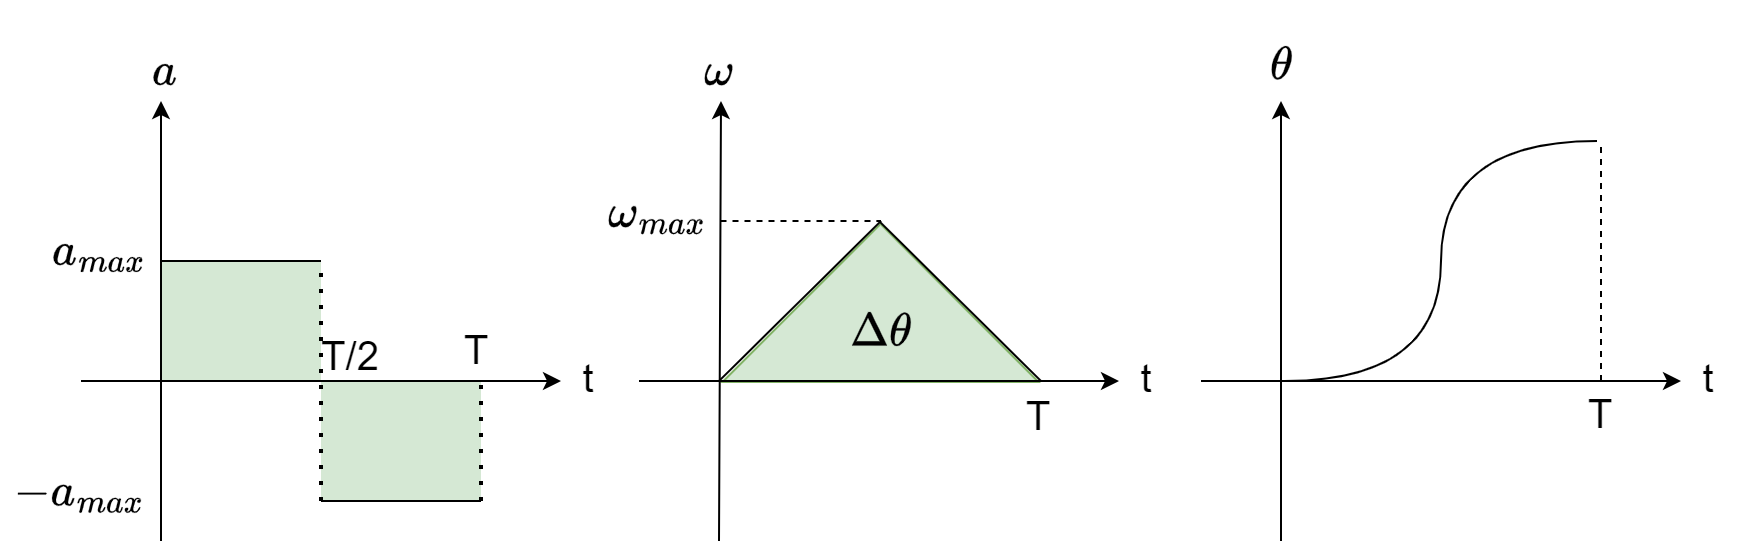**그림 1**

**2.1** Bang-off-bang 프로파일로부터 제약 조건 1번을 만족할 수 있는 리액션 휠 성능과, 제약 조건 2번을 만족할 수 있는 리액션 휠 성능 각각을 도출하시오.

% Parameter
I                   = 0.1;              % [kg m^2]
dtheta              = [10 ; 20].*D2R;   % [rad]
T                   = [15 ; 25];        % [sec]

% ==================== DIY ====================
% Case 1: dtheta=10deg, T=15
w_max_case1 = 2*dtheta(1)/T(1);
a_max_case1 = 2*w_max_case1/T(1);
torque_max_case1 = a_max_case1*I;
momentum_max_case1 = w_max_case1*I;
% Case 2: dtheta=20deg, T=25
w_max_case2 = 2*dtheta(2)/T(2);
a_max_case2 = 2*w_max_case2/T(2);
torque_max_case2 = a_max_case2*I;
momentum_max_case2 = w_max_case2*I;

disp(momentum_max_case1);

    0.0023



disp(momentum_max_case2);

    0.0028



disp(torque_max_case1);

   3.1028e-04



disp(torque_max_case2);

   2.2340e-04





% ==================== DIY ====================

- 제약조건 1을 만족하기 위해서는 먼저 리액션 휠의 최대 모멘텀은 0.0023[kg m^2/s], 리액션 휠의 최대 토크는 3.102e-04[ kg m^2/s^2]의 성능을 가져야한다.

- 제약조건 2를 만족하기 위해서는 먼저 리액션 휠의 최대 모멘텀은 0.0028[kg m^2/s], 리액션 휠의 최대 토크는 2.234e-04 [ kg m^2/s^2]의 성능을 가져야한다.

**2.2** 조건 1(15초에 10도)과 조건 2(25초에 20도) 중 더 큰 리액션 휠 모멘텀을 요구하는 경우는?

- 더 큰 리액션 휠 모멘텀의 경우 case 1의 경우 0.0023, case 2의 경우 0.0028 [kg m^2/s]으로 case2가 더 큰 모멘텀을 요구한다.

**2.3** 조건 1(15초에 10도)과 조건 2(25초에 20도) 중 더 큰 리액션 휠 토크를 요구하는 경우는?

- 더 큰 리액션 휠 토크의 경우 case 1의 경우 3.102e-04, case2의 경우 2.234e-04 [ kg m^2/s^2]로 case 1이 더 큰 리액셜 휠 토크를 요구한다.

**2.4** 문제 2.2와 2.3의 결과로부터 두 제약 조건을 모두 만족시킬 수 있는 리액션휠의 성능을 선정하고, 이문제로부터 얻을 수 있는 사실을 제시하라(힌트: 주어진 시간과 기동각에 따라 요구되는 토크와 모멘텀 비교)

- 두가지 제약 조건을 만족하기 위해서는 둘 중 더 큰 모멘트와 더 큰 토크의 성능을 리액션휠이 낼 수 있어야하므로, 리액션 휠이 낼 수 있는 최대 토크는 3.102e-04[ kg m^2/s^2] , 최대 모멘트는 0.0028 [kg m^2/s]로 선정해야 한다. 이러한 사실로 알 수 있는 점은 빠른 기동이 원하는 성능과 큰 각 기동이 원하는  성능이 차이가 있다는 점이다. case1과 같이 특정각에 빠르게 도달해야하는 경우에는 더 큰 토크를 요구하고, case2와 같이 시간보다는  큰 각 기동을 해야하는 경우는 더 큰 모멘텀을 요구한다. 즉, 빠른 기동은 토크 성능이, 큰 각도 기동은 모멘텀 용량이 설계의 제한 요소가 된다. 따라서 리액션 휠 선정 시 단일 성능 지표만으로는 부족하며, 토크와 모멘텀을 모두 고려해야 한다.

**2.5** 문제 2.4에서 결정한 휠의 성능을 그대로 이용하여 자세 프로파일을 생성해보자.

아래 그림은 Bang-off-bang 제어기에 의해 생성되는 자세 프로파일을 나타낸 것이다. Bang-off-bang 제어기는 요구되는 기동각이 큰 경우에 적용할 수 있는 제어 기법이다.

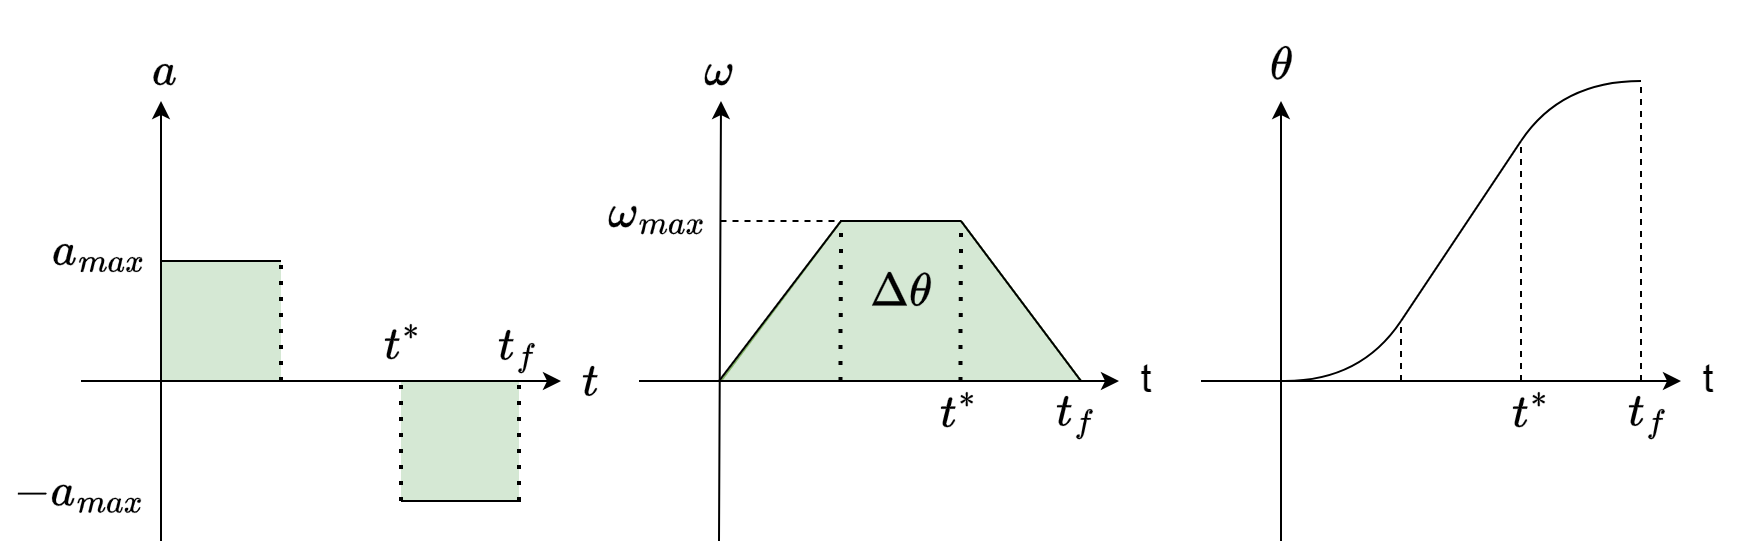**그림 2**

Bang-bang 제어기와 Bang-off-bang 제어기 중 어떤 방식을 사용할지 판단하는 기준은 다음과 같다. 먼저 요구 기동각을 $\Delta \theta$라고 하자. Bang-bang 제어기를 적용했을 때 도달 가능한 최대 기동각은 그림 1의 프로파일로 부터 다음과 같이 유도된다. 


$$\Delta \theta_{\mathrm{crit}} =\frac{\omega_{\max }^2 }{a_{\max } }$$


따라서 요구되는 기동각($\Delta \theta$)이 $\Delta \theta_{\textrm{crit}}$보다 크다면 Bang-off-bang 제어기를, 작으면 Bang-bang 제어기를 고려할 수 있다. 

이제 이를 코드로 구현해보자. 아래 코드에서는 문제 2.4에서 구한 $h_{\textrm{RW},\max } ,\tau_{\textrm{RW},\max }$를 입력값으로 사용한다. 또한 **요구 기동각이 (1) 5도, (2) 50도** 인 경우에 대해, Bang-bang 또는 Bang-off-bang 제어기를 적용하여 각각의 자세 프로파일이 생성되도록 함수를 구현한다.

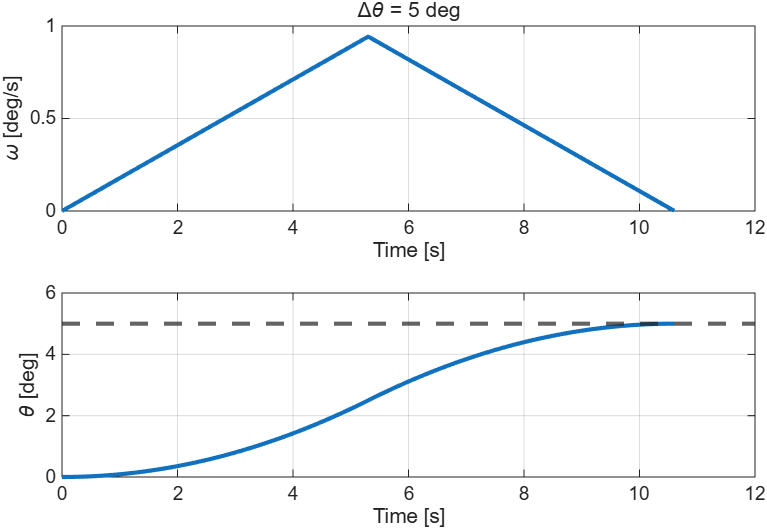

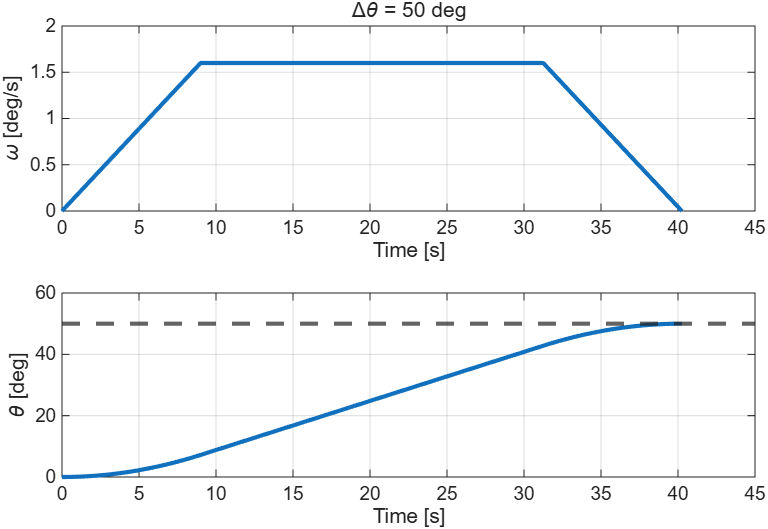

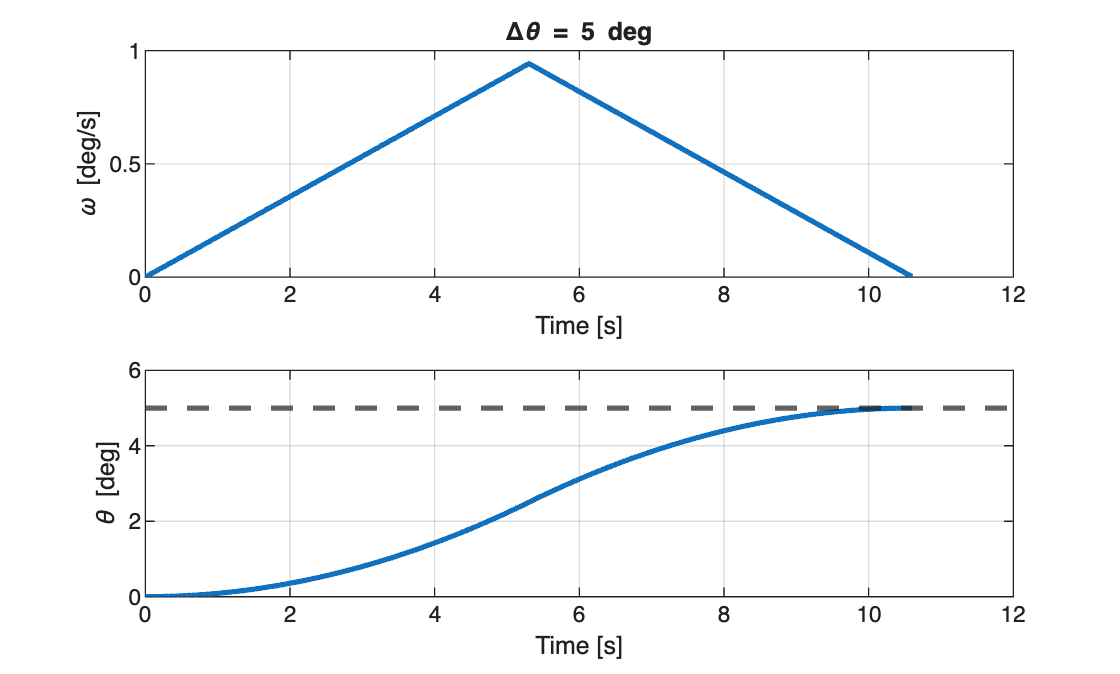

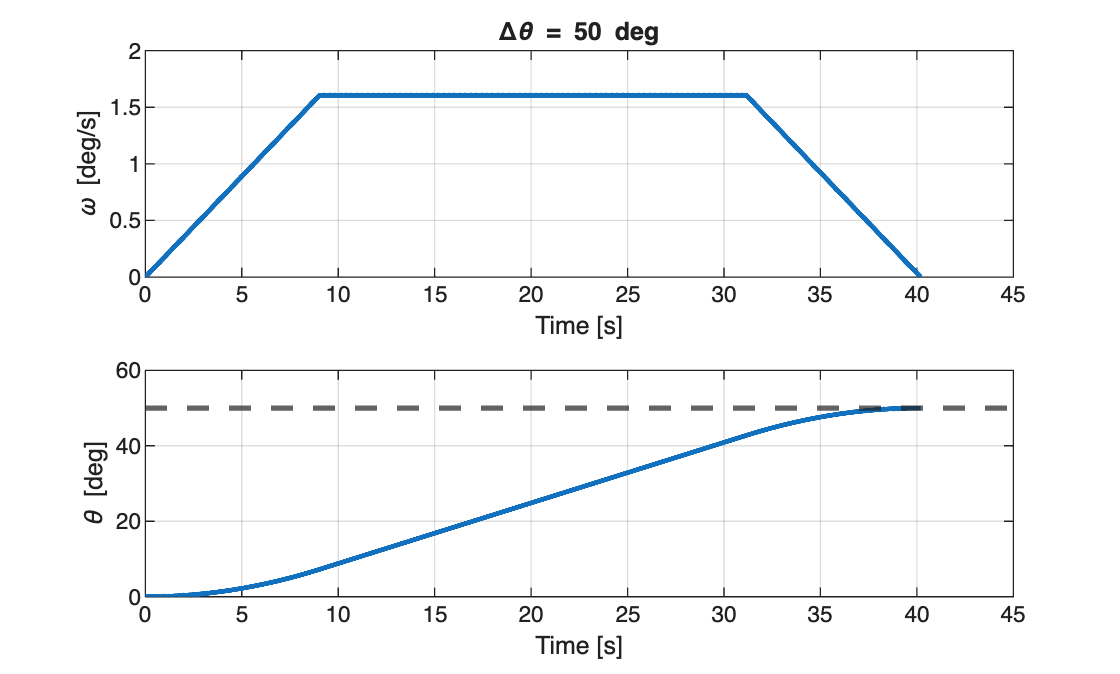

% Parameter @ Problem 2.1 ~ 2.4
I                   = 0.1;              % [kg m^2]

% ==================== DIY ====================
h_RW_max            = [0.0028];               % [N m s] reaction wheel momentum capacity
tau_RW_max          = [3.102e-04];               % [N m] reaction wheel torque capacity
% ==================== DIY ====================

% Maneuver Requirements
dt                  = 0.01;
dtheta              = [5 ; 50].*D2R;    % [rad]

if isempty(h_RW_max) && isempty(tau_RW_max)
    % Do nothing
else
    for k = 1 : length(dtheta)
        w_max = h_RW_max / I;
        a_max = tau_RW_max / I;

        dtheta_temp = dtheta(k);

        [t, omega, theta, acc] = make_att_profile(dtheta_temp, w_max, a_max, dt);

        % Plot
        figure;
        subplot(2,1,1) % t-w
        plot(t, omega.*R2D , 'LineWidth',2)
        grid on
        xlabel('Time [s]')
        ylabel('\omega [deg/s]')
        title(sprintf('\\Delta\\theta = %.0f deg', dtheta_temp*R2D))
        subplot(2,1,2) % t-theta
        plot(t, theta.*R2D , 'LineWidth',2)
        hold on
        yline(dtheta_temp*R2D,'LineWidth',2,'LineStyle','--')
        grid on
        xlabel('Time [s]')
        ylabel('\theta [deg]')      

    end
end


% ==================== DIY ====================
function [t, omega, theta, acc] = make_att_profile(dtheta, w_max, alpha_max, dt)

    % Critical angle required to reach maximum angular velocity
    dtheta_crit = w_max^2 / alpha_max;
    
    if dtheta >= dtheta_crit
        %% Bang-off-bang profile
        t_star = dtheta/w_max;
        tf = t_star + w_max/alpha_max;
        t = 0:dt:tf;
        omega = zeros(size(t));
        acc = zeros(size(t));

        for i = 1:length(t)
            if t(i) <= (tf - t_star)
                acc(i)   = alpha_max;
                omega(i) = alpha_max * t(i);
            elseif t(i) <= t_star
                acc(i) = 0;
                omega(i) = w_max;
            else 
                acc(i) = -alpha_max;
                omega(i) = w_max-alpha_max*(t(i)-t_star);
            end
 
        end
         
    
    else
        %% Bang-bang profile
        tf    = 2*sqrt(dtheta/alpha_max);
        %tf = 2*w_max / alpha_max;
        t = 0:dt:tf;
        omega = zeros(size(t));
        acc = zeros(size(t));
        
        for i = 1:length(t)
            if t(i) <= tf/2
                acc(i) = alpha_max;
                omega(i) = alpha_max * t(i);

            else 
                acc(i) = -alpha_max;
                omega(i) = -alpha_max*(t(i)-tf);

            end
        end

    end
    theta = cumsum(omega)*dt;
end
% ==================== DIY ====================

**2.6** 이제 Agility table을 만들어보자. 기동각 $\Delta \theta =\left\lbrack \begin{array}{cccc}
5^{\circ }  & {10}^{\circ }  & \cdots  & {50}^{\circ } 
\end{array}\right\rbrack$ 일때, 각각에 대해 몇초 만에 도달할 수 있는지 아래와 같은 그래프를 만들어보자.

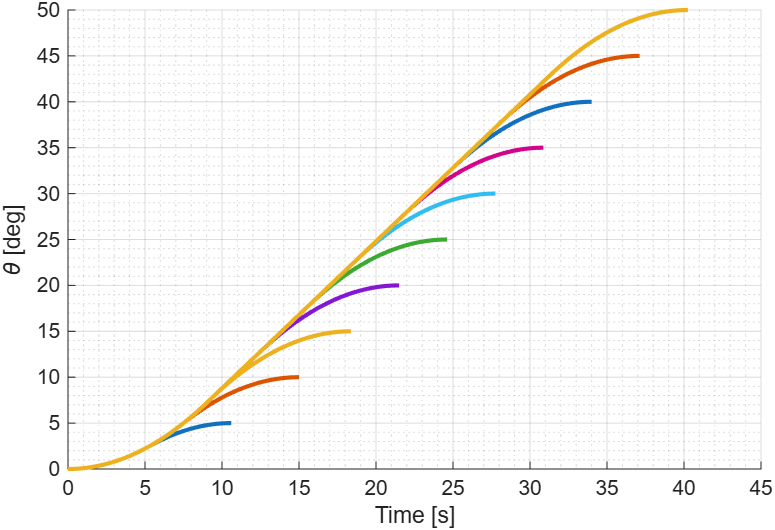

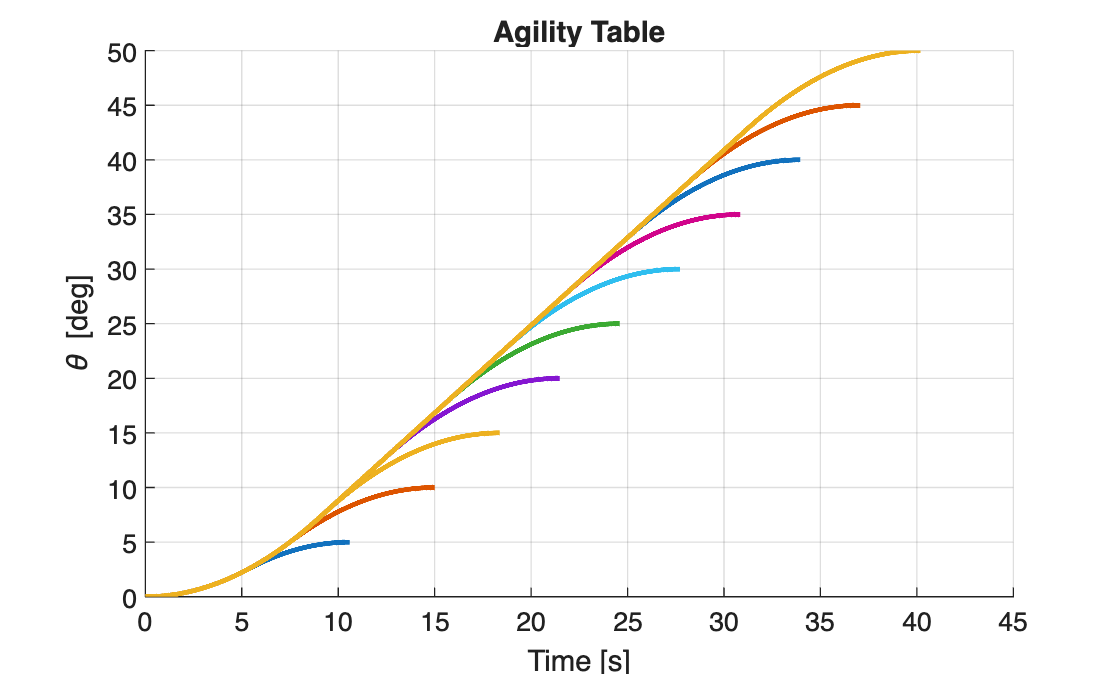

dtheta              = (5:5:50).*D2R;    % [rad]
data_len            = length(dtheta);

if isempty(h_RW_max) && isempty(tau_RW_max)
    % Do nothing
else
    % ==================== DIY ====================
    figure;
    hold on;
    for k = 1:data_len
        w_max = h_RW_max / I;
        a_max = tau_RW_max / I;
        dtheta_temp = dtheta(k);
    
        [t, omega, theta, acc] = make_att_profile(dtheta_temp, w_max, a_max, dt);
    
        plot(t, theta.*R2D, 'LineWidth', 2)
    end
    hold off;
    grid on;
    ax = gca;
    ax.XTick = 0:5:45;
    ax.YTick = 0:5:50;
    xlabel('Time [s]')
    ylabel('\theta [deg]')
    title('Agility Table')
    % ==================== DIY ====================
end